#    R7020E Lab 4

## Task 1

Declare paths and find all images in that folder

files = [dir(fullfile("./calibration/mav0/cam0/data","*.png")),...
        dir(fullfile("./calibration/mav0/cam1/data","*.png"))];             % Load the datasets
assert(length(files(1)) == length(files(2)));                               % Make sure that the dataset is not missing any frames

Now go over every nth frame until we have k calibration images

n = 40;                                                                     % Time skip size
k = 40;                                                                     % Number of frames in the dataset we want

Create a calibration set

calib = [[],[]];
% The boardpoints in the image
count = 0;
calib_set_l = cell(1,k);
calib_set_r = cell(1,k);
for i = 1:n:length(files)
    if count > k
        break;
    end
    % Left and right frame
    lf = imread(fullfile(files(i,1).folder,files(i,1).name));
    rf = imread(fullfile(files(i,2).folder,files(i,2).name));


We only want to calibrate on frames that have checkerboards in them, this is a bit redundant, but only needs to be done once

    [ip,~,~] = detectCheckerboardPoints(lf,rf); % This warning is ok since the returns are just discarded
    if ~isempty(ip)
        % We found a good image
        count = count+1;
        calib_set_l{count} = fullfile(files(i,1).folder,files(i,1).name);
        calib_set_r{count} = fullfile(files(i,2).folder,files(i,2).name);
    end
end

Now we have a calibration set, now we can use the checkboard corners in the images to calibrate the cameras

% Boardpoints in the images
[imp,s,~] = detectCheckerboardPoints(calib_set_l,calib_set_r);
% Theoretical board points, with fixed dimensions
bp = generateCheckerboardPoints(s,60); % World is in mm
% Stereo param ( sp ), drop all the other returns. SP is now relative to
% the left camera

Here we should probably use the matricies supplied in the the yaml files but since I do not know why the extrinsic matrix supplied is a 4x4 matrix and not a 3x3 ( like in all of the sources that I could find online ) I am going to use the estimate CameraParameters function supplied by matlab, this likely causes the error in distances since the discreppency between pixels will be underestimated when the cameras are to close.

I_0 = imread(fullfile(files(1,1).folder,files(1,1).name));
[sp,~,~]= estimateCameraParameters(imp,bp,"ImageSize",size(I_0));
clearvars('-except', "sp");
% Preserve image size
% Save the mat file
save("StereoParams.mat","sp");

Here are the camera parameters that will be used in task 2, all distance measures are relative to camera 0.

- Camera 0 intrinsics

disp(sp.CameraParameters1.IntrinsicMatrix)

  464.7450         0         0
         0  464.4743         0
  364.0186  249.0908    1.0000



- Camera 1 intrinsics

disp(sp.CameraParameters2.IntrinsicMatrix)

  463.8606         0         0
         0  463.7799         0
  374.7559  255.4758    1.0000



- Camera 1 pose relative to camera 1

disp(sp.PoseCamera2.A)

    1.0000    0.0022    0.0051 -109.8883
   -0.0023    0.9999    0.0148    0.4452
   -0.0051   -0.0148    0.9999    1.8001
         0         0         0    1.0000



Camera extrinsics

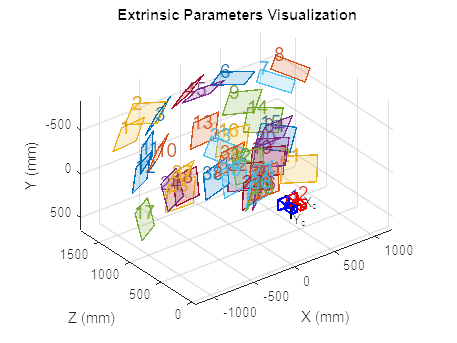

figure;showExtrinsics(sp); 

% Show the camera extrinsics

## Task 2

Now that we have the calibrated stereo pair we can calibrate the distances in the depth dataset

First we declare the dataset

files = [dir(fullfile("./depth/MH_01_Easy_cam/cam0/","*.png")),...
        dir(fullfile("./depth/MH_01_Easy_cam/cam1/","*.png"))];             % Load the datasets
assert(length(files(1)) == length(files(2)));                               % Make sure that the dataset is not missing any frames

Now we can compute harris corners and generate SIFT descriptors for each and every point

and then we can use that data to find distances

### Depth and stereo images at time_step = 2

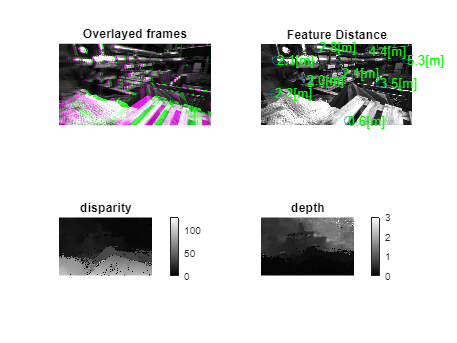

show_at_frame(2,files,sp,10);

### Depth and stereo images at time_step = 30

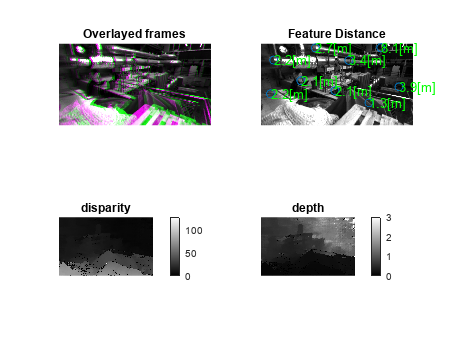

show_at_frame(30,files,sp,10);

### Depth and stereo images at time_step = 40

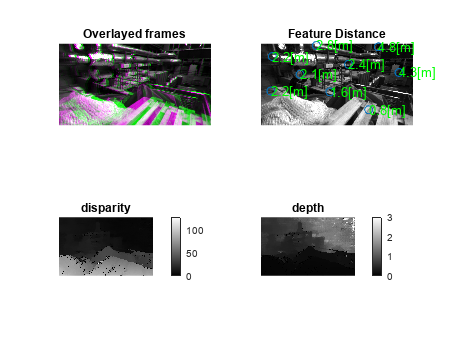

show_at_frame(40,files,sp,10);

Wrapping it in a function to allow calls to a certain frame

function show_at_frame(i,files,sp,max_features)
    figure;
    % Load and undistort the images
    lf = imread(files(i,1).folder+"/"+files(i,1).name);     % Load
    rf = imread(files(i,2).folder+"/"+files(i,2).name);     % Load
    [lf,rf] = rectifyStereoImages(lf,rf,sp,"nearest");
    subplot(2,2,1);
    frames = imfuse(lf,rf,'falsecolor','Scaling','joint');
    imshow(frames);
    title("Overlayed frames")

To Create a sparse depth map, I will use sift features since they are scale invariant.

    % Detect features in the left and right images
    lfeat = detectSIFTFeatures(lf);
    rfeat = detectSIFTFeatures(rf);
    % Only keep best points
    best = 1000;
    % Get the descriptors
    [lf_desc,lf_pos] = extractFeatures(lf,lfeat);
    [rf_desc,rf_pos] = extractFeatures(rf,rfeat);
    % Match the descriptors
    matched = matchFeatures(lf_desc,rf_desc);
    ptk = min([max_features,length(matched)]);
    lptk = [];      % Left points to keep
    rptk = [];      % Right points to keep
    % Find all points that are atleast somewhat spread out
    for index  = 1:size(matched,1)
        if length(lptk) > ptk
            break
        end
        pos_l = lf_pos(matched(index,1)).Location;
        pos_r = rf_pos(matched(index,2)).Location;
        if length(lptk) == 0
            lptk = [lptk;pos_l];
            rptk = [rptk;pos_r];
            continue
        end
        % Check that distance to closest element in lptk and rptk is
        % atleast threshold
        threshold = 200;
        min_l = inf;
        for j = 1:size(lptk,1)
            if norm(pos_l-lptk(j,:)) < min_l
                min_l = norm(pos_l-lptk(j,:));
            end
        end
        min_r = inf;
        for j = 1:size(rptk,1)
            if norm(pos_r-rptk(j,:)) < min_r
                min_r = norm(pos_r-rptk(j,:));
            end
        end
        if min_r > threshold && min_l > threshold
            lptk = [lptk;pos_l];
            rptk = [rptk;pos_r];
        end
    end

Now that we have a bunch of valid points we need to find the z distance for every point

    % Now find the distance for every interest point
    x = lptk(:,1);%lp.Location(:,1);
    y = lptk(:,2);%lp.Location(:,2);
    dist = zeros(1,size(lptk,1));
    for itter = 1:size(lptk,1)  
        d = (triangulate(round(lptk(itter,:)),round(rptk(itter,:)),sp))./1000;
        dist(itter) = sqrt(sum(d.^2));
    end

    subplot(2,2,2);
    imshow(lf);
    title("Feature Distance");
    % Draw distances
    hold on
    scatter(x,y);
    for j = 1:length(dist)
        lable = sprintf("%.1f[m]",norm(dist(j)));
        text(x(j),y(j),lable,"Color",'g');
    end
    hold off

Now create a disparity map, this is done using matlabs builtins, but it's quite easy to implement a slow equivalent, just do region matching for every pixel

    % Now let's create a disparity map
    d = disparitySGM(lf,rf,"UniquenessThreshold",2);
    subplot(2,2,3);
    imshow(d(:,128:end),[0,128]);
    title disparity;
    colorbar

Create a depth map from the disparity map

    depth = calc_depth_from_disparity(d,sp);
    subplot(2,2,4);
    imshow(depth(:,128:end)./1000,[0,3]);
    title depth;
    colorbar
end


To compute the depth map, just convert pixel offsets to real world units according to the formula described in lecture 9.

function disp = calc_depth_from_disparity(disp,stereoparams)
    cp1 = stereoparams.CameraParameters1;
    cp2 = stereoparams.CameraParameters2;
    % Find the focal lengths
    f1 = cp1.FocalLength;
    f2 = cp2.FocalLength;
    % Mean focal length in mm/pixel
    f = mean([f1(1),f1(2),f2(1),f2(2)]);
    % Find the optical centers
    c1 = cp1.IntrinsicMatrix(3,1:2);
    c2 = cp2.IntrinsicMatrix(3,1:2);
    % Calculate distance between principle points 
    % in mm
    T = sqrt(sum((c1(:)-c2(:)).^2));
    for x = 1:size(disp,1)
        for y = 1:size(disp,2)
            disp(x,y) = (T*f/disp(x,y));
        end
    end
    
end